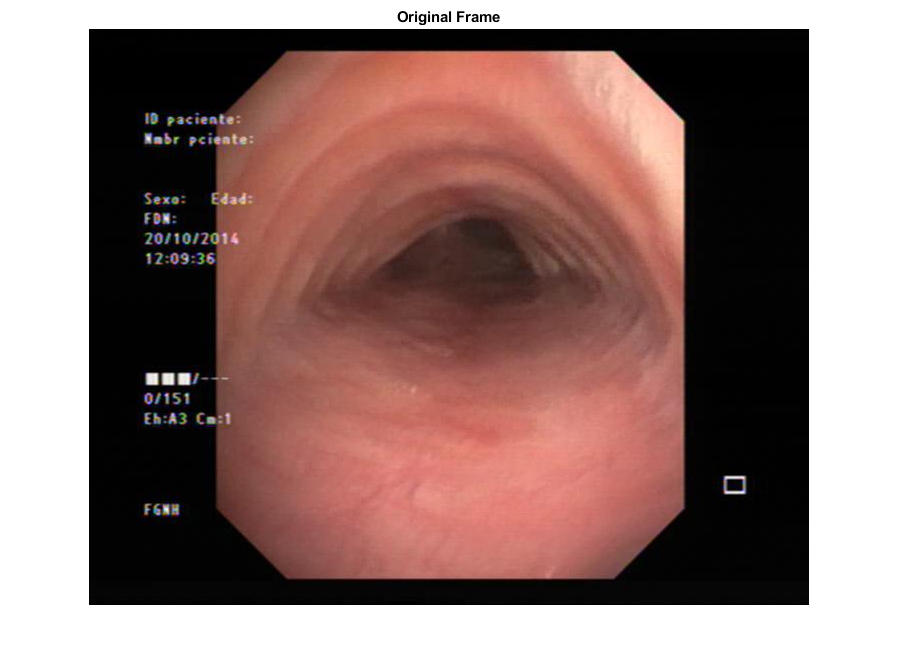

% cd frames\sick1\

% frame = imread('676.jpg');
% frame = imread('112.jpg');
frame = imread('120.jpg');
imshow(frame);
title('Original Frame');

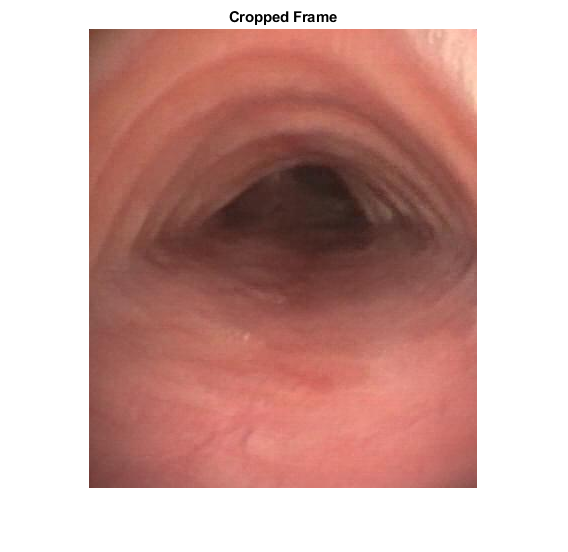


% //////// PREPROCESSING \\\\\\\\\\
% ------- Image Cropping ----------
frameCropped = imcrop(frame,[168,54,387,458]);
imshow(frameCropped);
title('Cropped Frame');

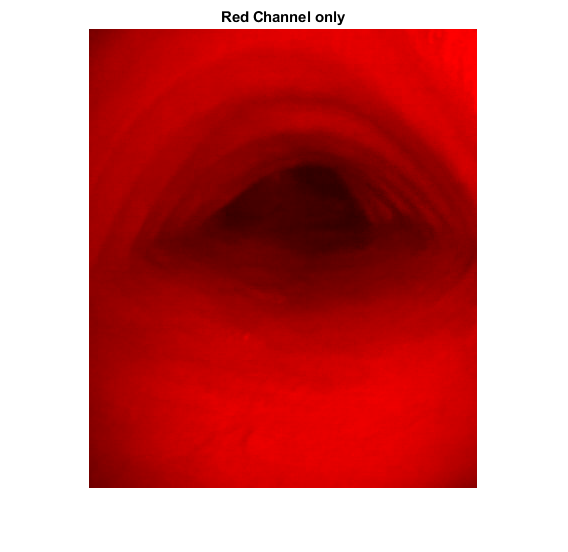

% ---------------------------------

% //////// BEST FEATURES \\\\\\\\\\
% ----------- Redness -------------
frameRChannel = frameCropped(:,:,1);
% Create an all black channel.
allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
% Create a color version of the Red Channel
frameRed = cat(3, frameRChannel, allBlack, allBlack);
% Print red channel
imshow(frameRed);
title('Red Channel only');

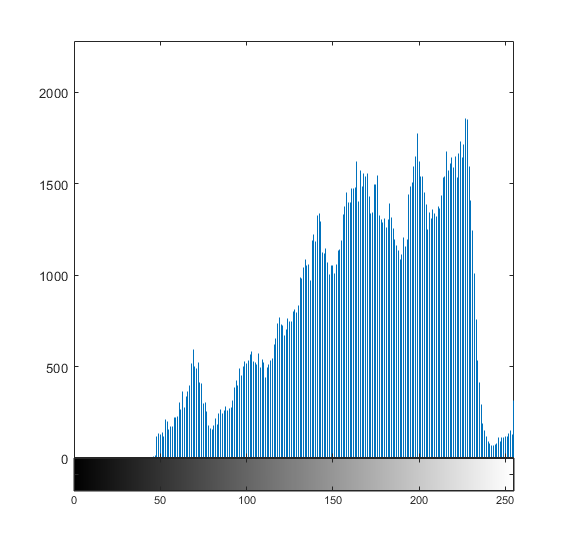

imhist(frameRChannel);

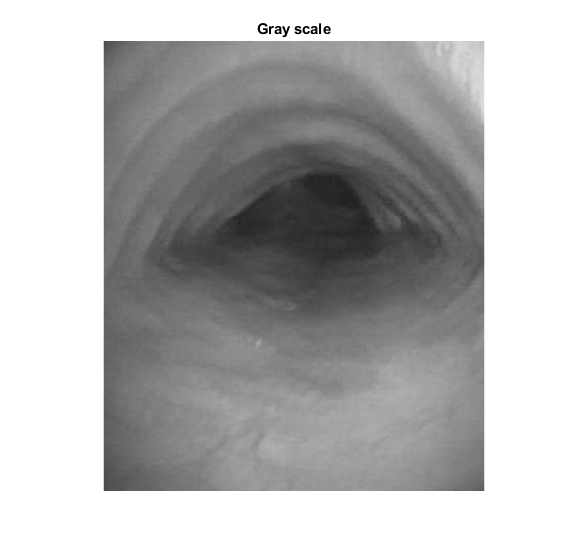

% ----------- Grayness ------------
frameGray = rgb2gray(frameCropped);
imshow(frameGray);
title('Gray scale');

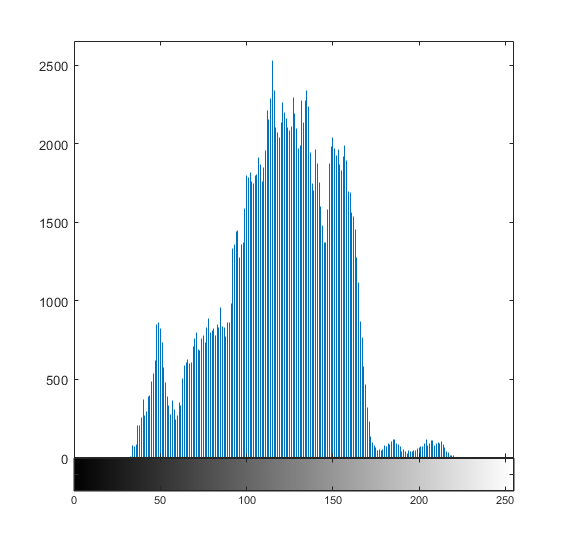

imhist(frameGray);

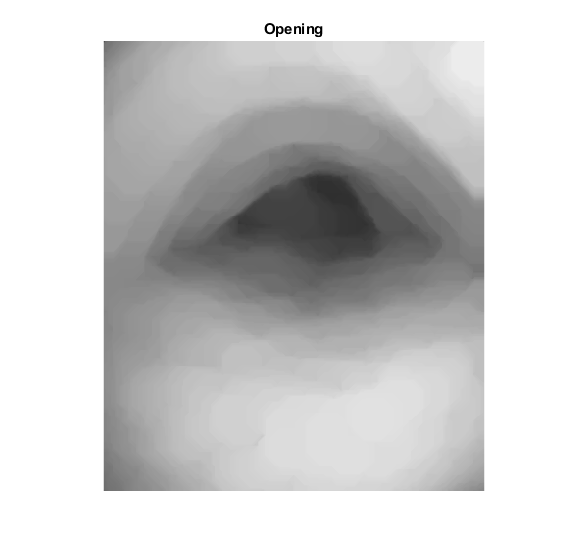

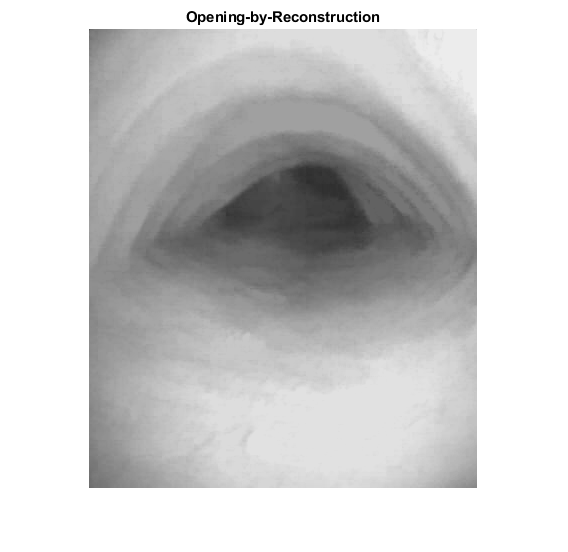

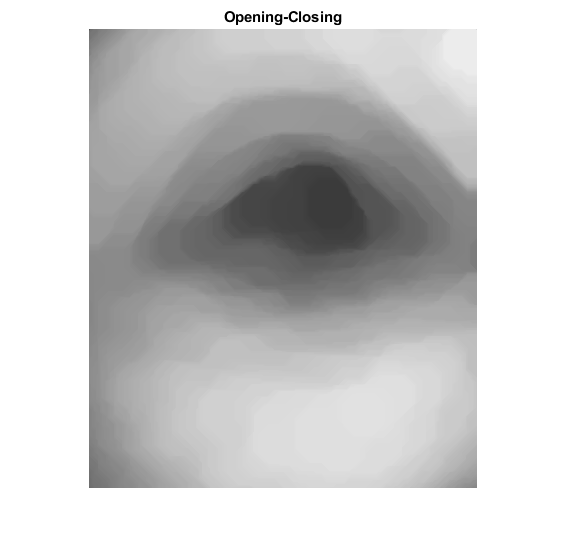

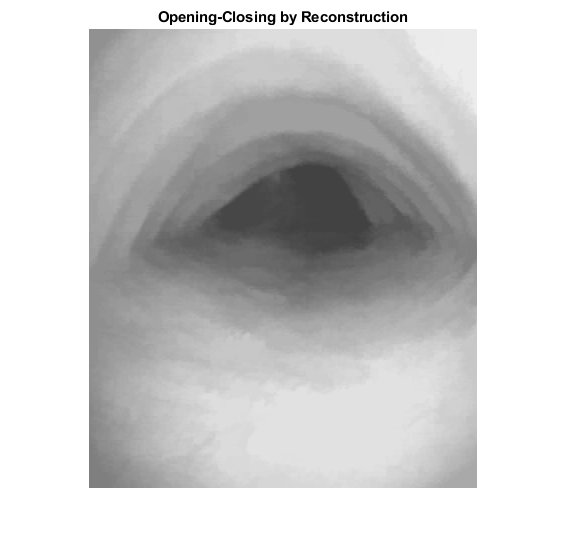

% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////
% Filterage of frame
preProcessedFrame = openCloseByReconstruction(frameRChannel);

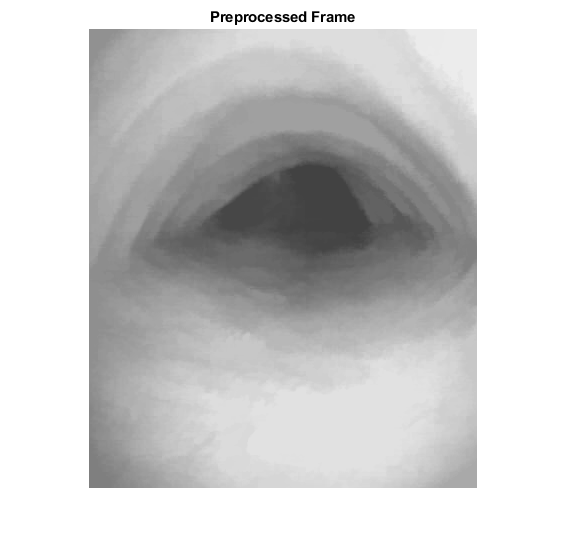

imshow(preProcessedFrame);
title('Preprocessed Frame')

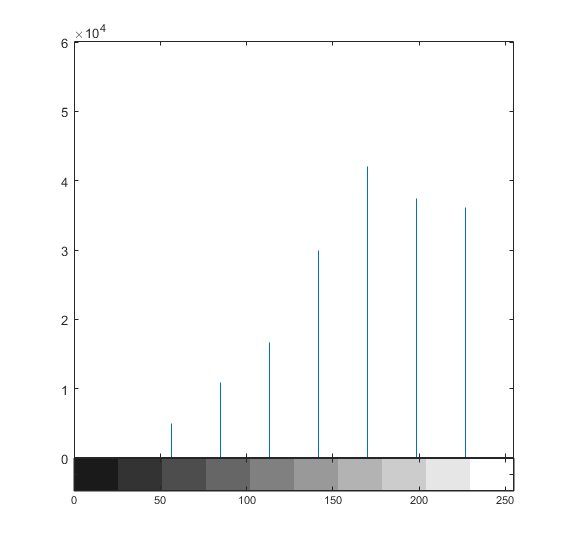

% \\\\\\\\\\\\\\\|/////////////////

% ///////// SEGMENTATION \\\\\\\\\\
% --------- Binarization ----------
% Image histogram with 10 bins

% Hist binaritzation
binFrameManual = binBinarization(preProcessedFrame,10);

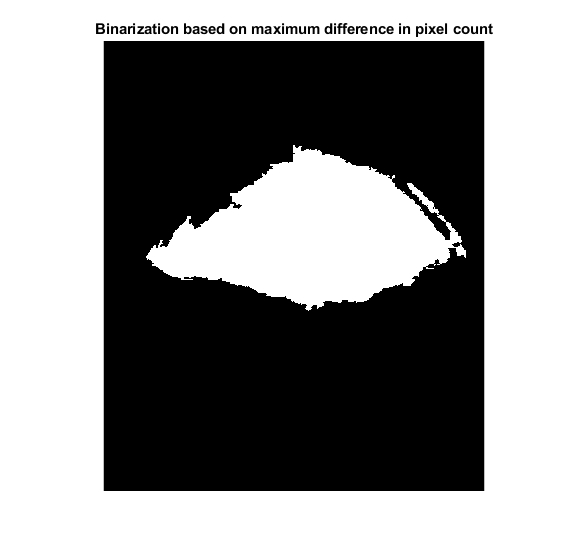


% Otsu binarization
level = graythresh(preProcessedFrame);
binFrameOtsu = imbinarize(preProcessedFrame,level);

% Adaptive binarization
binFrameAdaptive = imbinarize(preProcessedFrame,"adaptive", ...
    "ForegroundPolarity","bright","Sensitivity",0.66);

% Image Printing
imshow(binFrameManual);
title('Binarization based on maximum difference in pixel count');

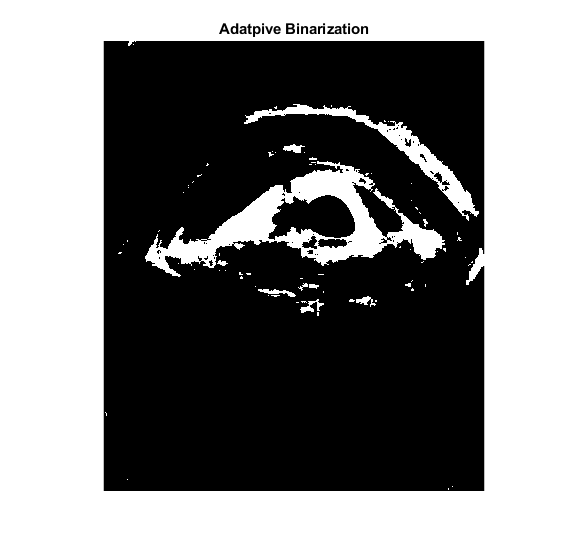

%imshow(~binFrameOtsu);
%title('Otsu binarization');
imshow(~binFrameAdaptive);
title('Adatpive Binarization');

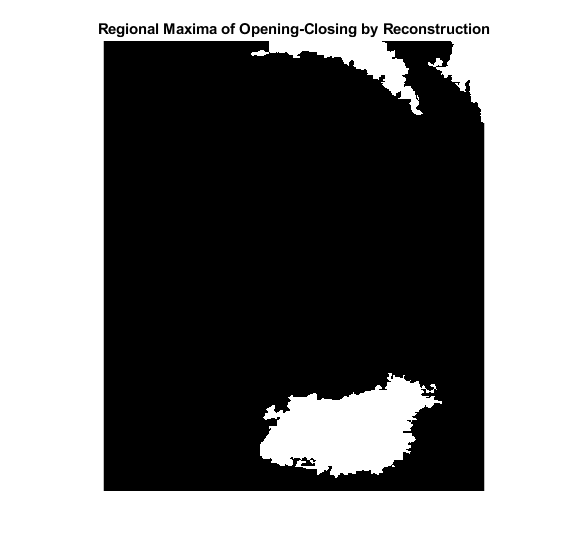

% ---------------------------------

% ---------- Watershed ------------
maximums = imregionalmax(preProcessedFrame);
imshow(maximums)
title('Regional Maxima of Opening-Closing by Reconstruction')

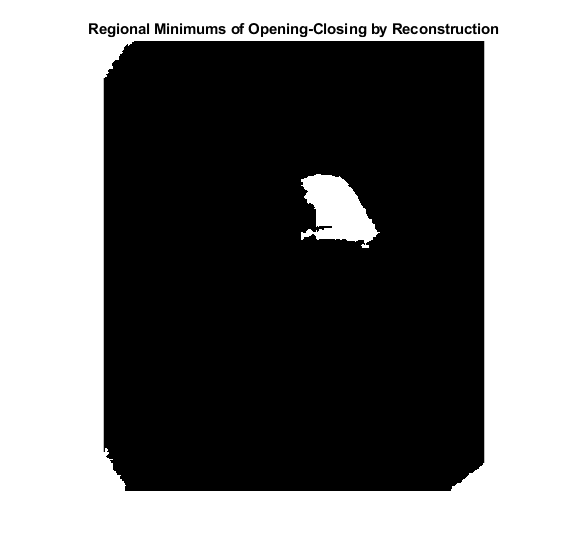


minimums = imregionalmin(preProcessedFrame);
imshow(minimums)
title('Regional Minimums of Opening-Closing by Reconstruction')

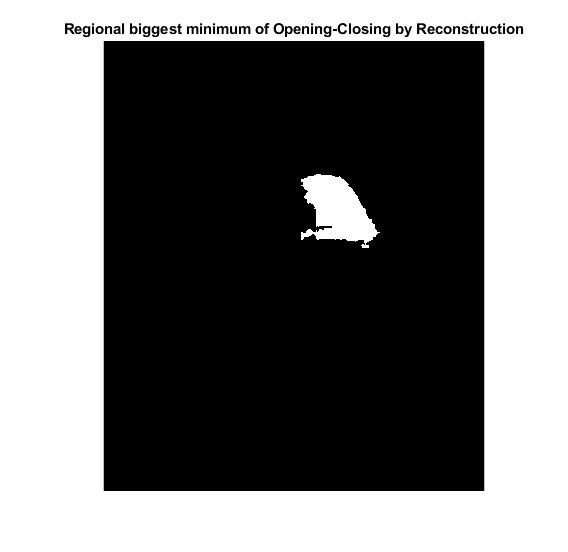


minimum = ExtractNLargestBlobs(minimums, 1);
imshow(minimum)
title('Regional biggest minimum of Opening-Closing by Reconstruction')

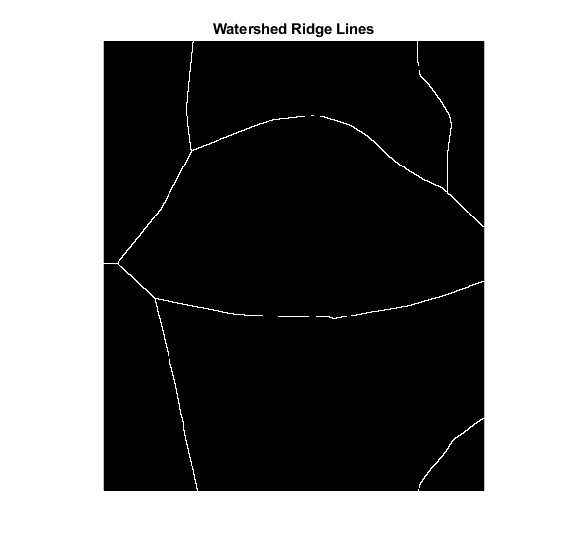


D = bwdist(maximums | minimums);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Watershed Ridge Lines')

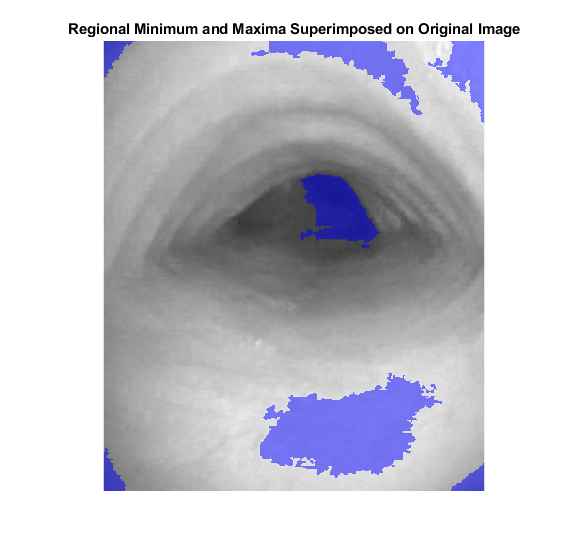


I2 = labeloverlay(frameRChannel,minimums | maximums);
imshow(I2)
title('Regional Minimum and Maxima Superimposed on Original Image')

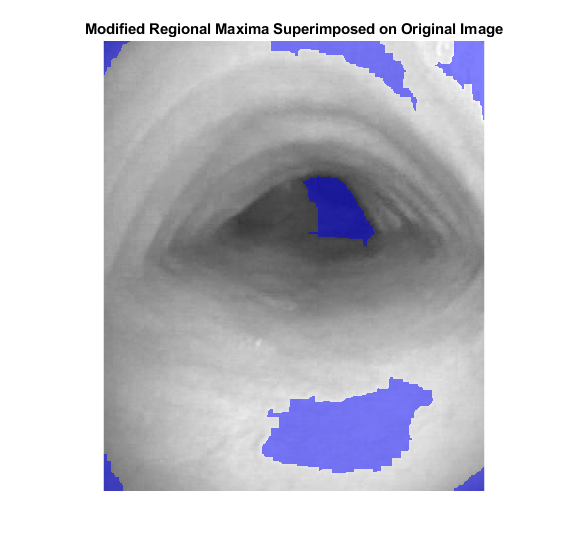


se2 = strel(ones(5,5));
fgm2 = imclose(minimums | maximums,se2);
fgm3 = imerode(fgm2,se2);
fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(frameRChannel,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')

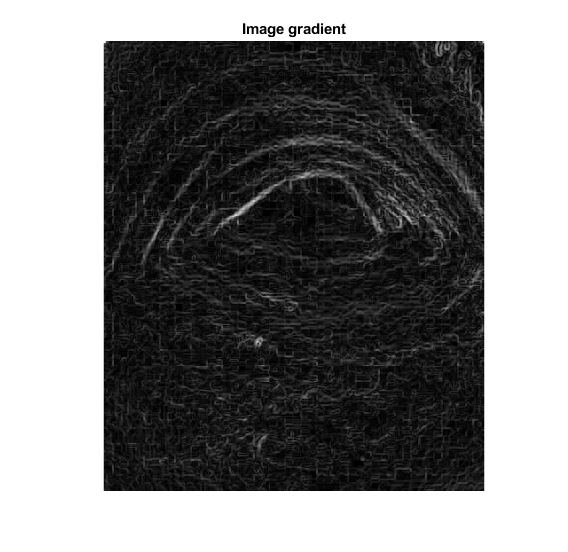


% Gradient of the image
gmag = imgradient(frameRChannel);
imshow(gmag,[]);
title('Image gradient')

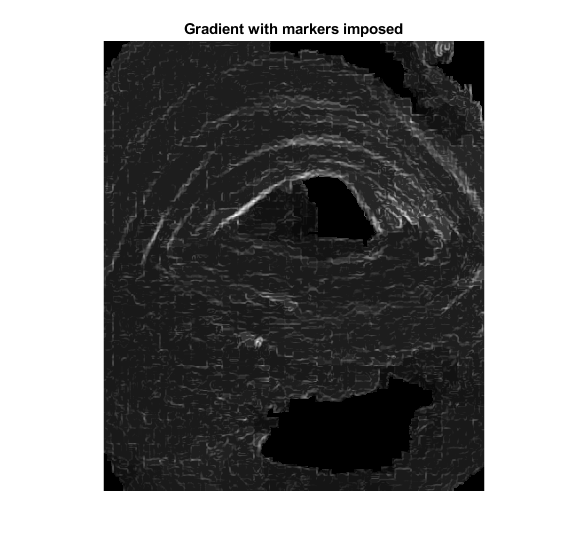


gmag2 = imimposemin(gmag, fgm4);
imshow(gmag2,[])
title('Gradient with markers imposed')

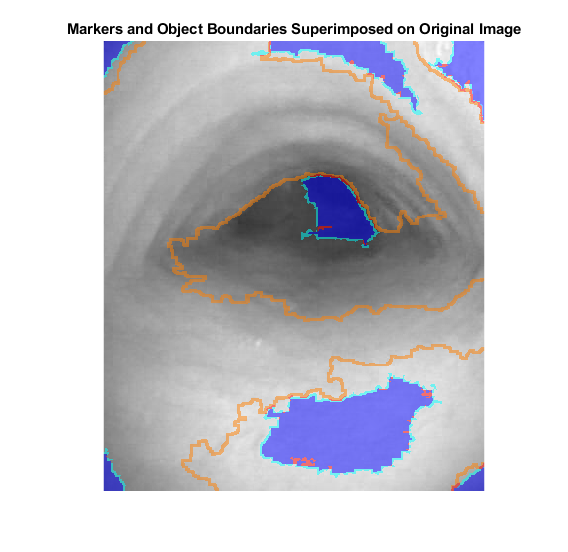

L = watershed(gmag2);
labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm4;
I4 = labeloverlay(frameRChannel,labels);
imshow(I4)
title('Markers and Object Boundaries Superimposed on Original Image')

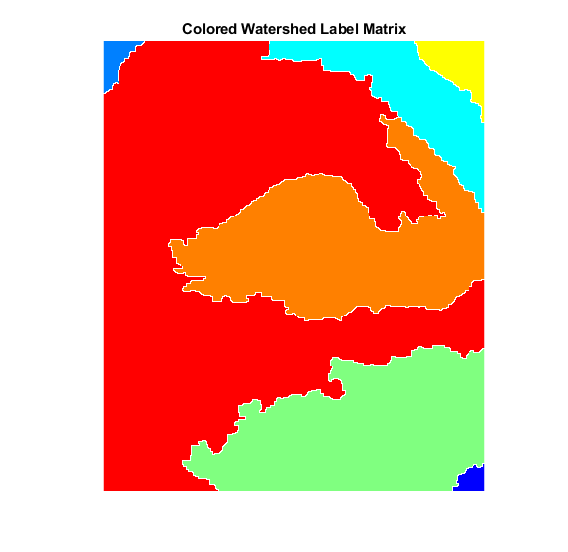

% labeling the watershed results
Lrgb = label2rgb(L,'jet','w','shuffle');
imshow(Lrgb)
title('Colored Watershed Label Matrix')

% Getting the the value of the labels for the biggest minimum blob in the frame
labelValue = L(minimum)

labelValue = 3531×1 uint8 column vector
   5
   5
   5
   5
   5
   5
   5
   5
   5
   5


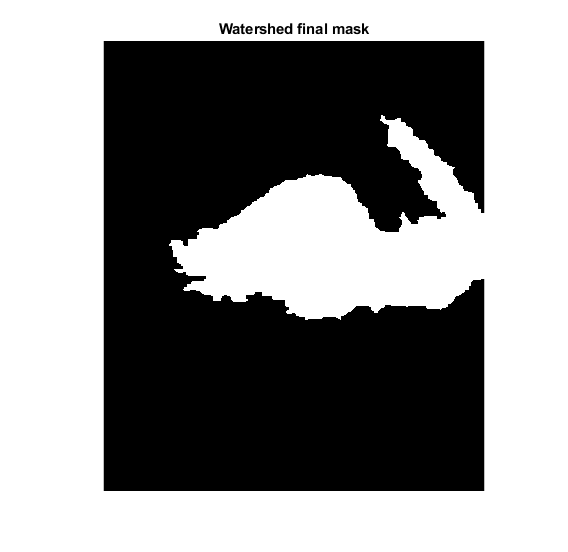

% Getting the label with maximum ocurrence
value = mode(labelValue);
% Getting the watershed segmentation of the stenosis level
watershedSegmentation= L == value;
imshow(watershedSegmentation);
title('Watershed final mask')

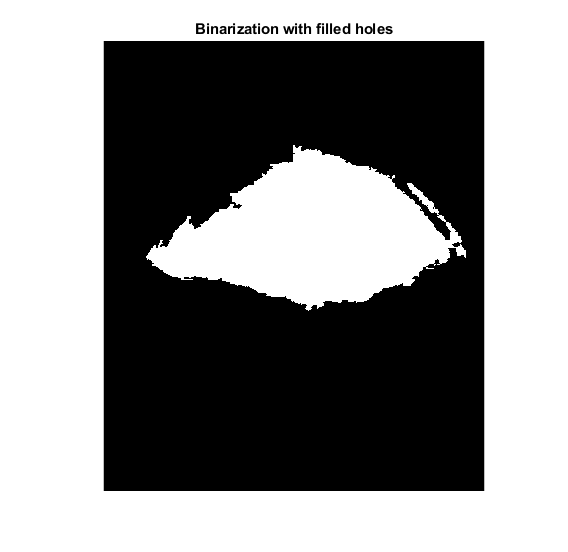

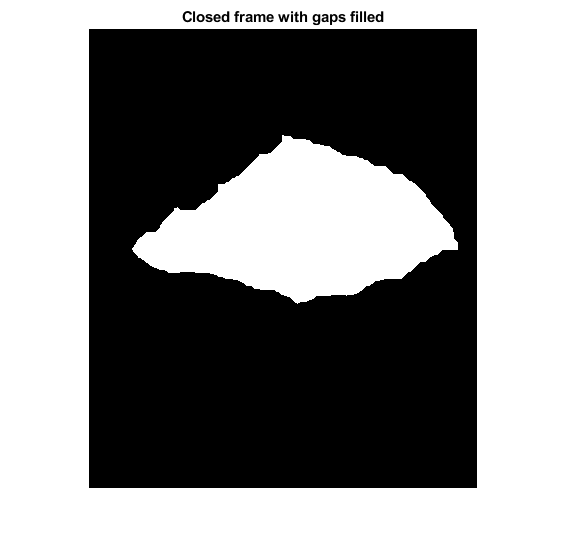

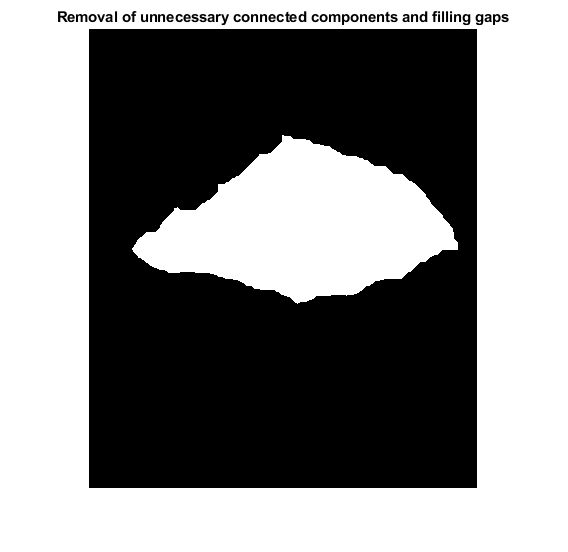

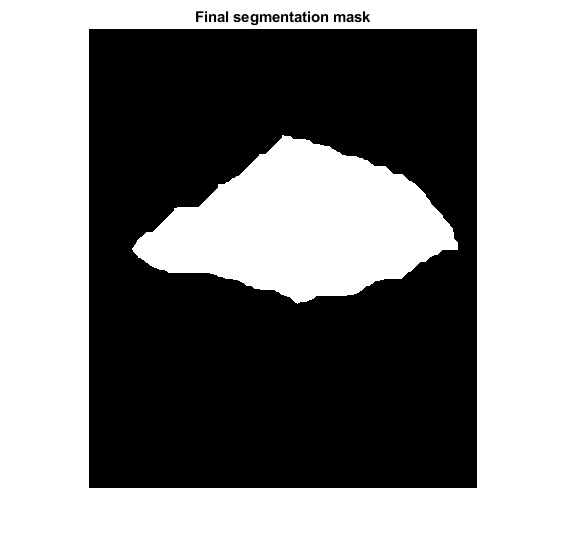

% ---------------------------------
% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////

% //////// POSTPROCESSING \\\\\\\\\\
closeDiffBlobFrame = getSegment(binFrameManual);

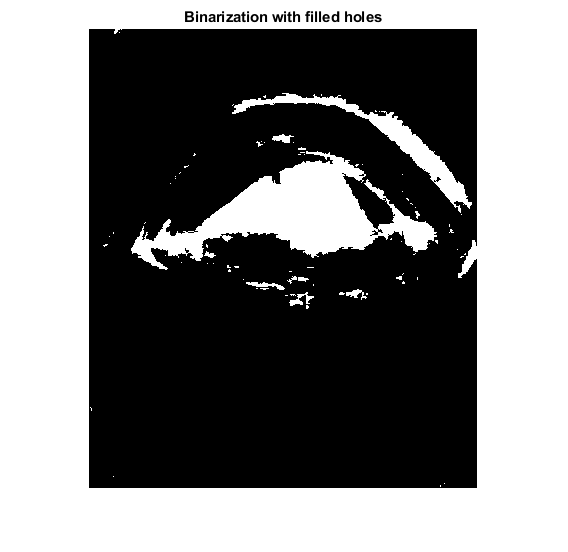

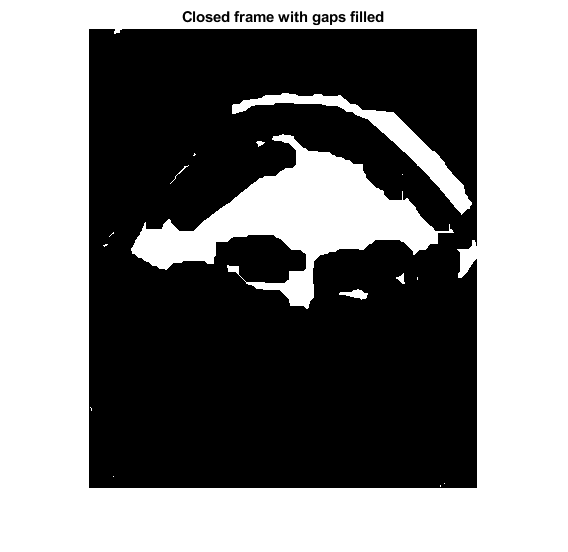

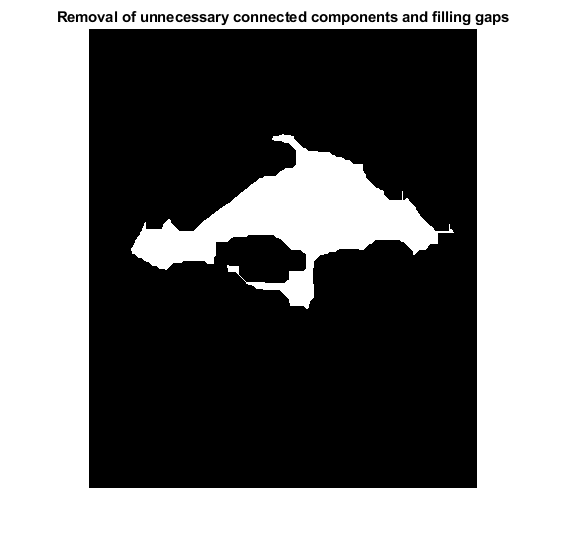

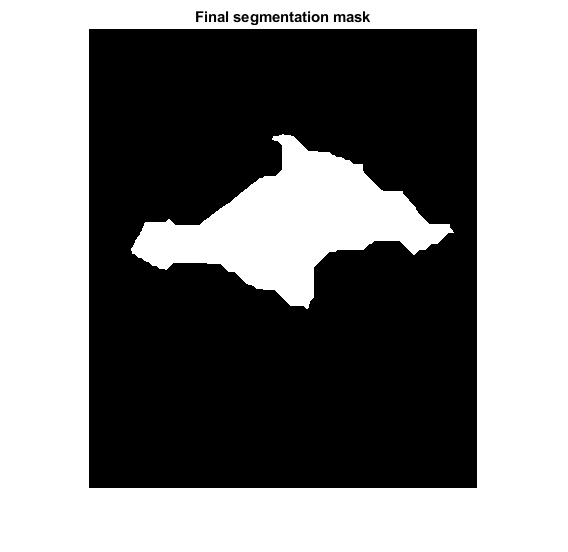

closeAdaptiveBlobFrame = getSegment(~binFrameAdaptive);

% \\\\\\\\\\\\\\\|/////////////////

% Getting the area
maxDiffArea = bwarea(binFrameManual)

maxDiffArea = 3.0517e+04

waterArea = bwarea(watershedSegmentation)

waterArea = 3.3639e+04

binArea = bwarea(closeAdaptiveBlobFrame)

binArea = 2.3131e+04

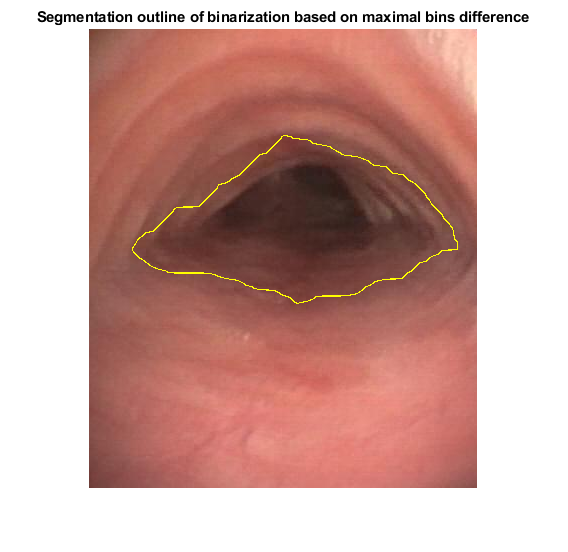

% Max diff result
segmentationOutline(frameCropped, closeDiffBlobFrame);
title('Segmentation outline of binarization based on maximal bins difference');

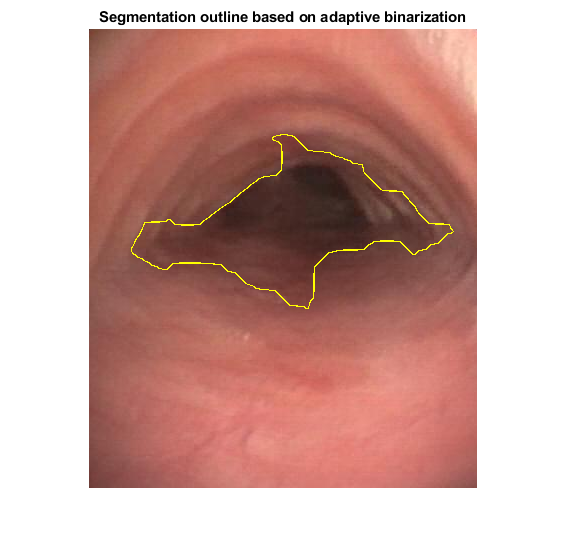

% Adaptive result
segmentationOutline(frameCropped, closeAdaptiveBlobFrame);
title('Segmentation outline based on adaptive binarization');

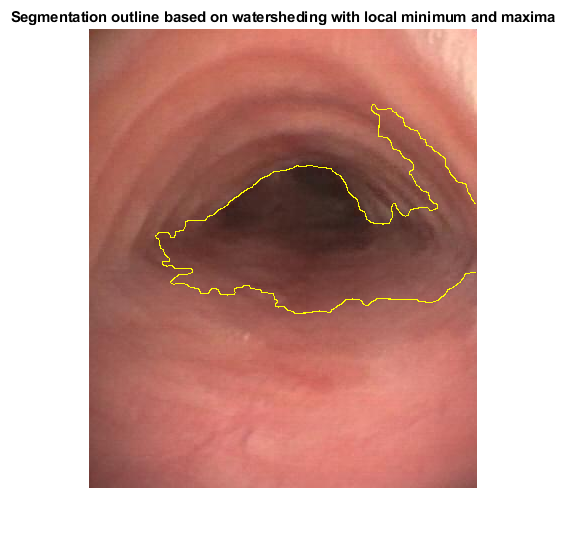

% Watershed result
segmentationOutline(frameCropped, watershedSegmentation);
title('Segmentation outline based on watersheding with local minimum and maxima');


% cd ..\..\


function mask = binBinarization(frame,bins)
    imhist(frame,bins);
    [counts,binLocations] = imhist(frame,bins);
    %counts = counts(1:size(counts));
    %binLocations = binLocations(1:size(binLocations));
    % Getting maximum difference between bins
    [dist,ix] = max(diff(counts));
    % Setting the threshold using the % of divergence between bins
    countDiff = (counts(ix) * 100) / counts(ix + 1);
    binDiff = binLocations(ix + 1) - binLocations(ix);
    binThresh = binLocations(ix) + binDiff * ((100-countDiff)/100);
%     if (counts(ix) > 0 && counts(ix) > counts(ix + 1)*0.25)
%         % Setting the threshold to the difference
%         binThresh = ceil(abs((binLocations(ix + 1) + binLocations(ix))) / 2)
%     elseif (counts(ix))
%         binThresh = binLocations(ix + 1);
%     end
    mask = frame <= binThresh;
end
function segmentationOutline(frame, segmentation)
    edgeDetected = edge(segmentation,"canny");
    frameOutlined = imoverlay(frame,edgeDetected,'yellow');
    imshow(frameOutlined);
end

function openClosedImage = openCloseByReconstruction(frame)    
    se = strel('disk',20);
    Io = imopen(frame,se);
    imshow(Io)
    title('Opening')
    figure
    
    Ie = imerode(frame,se);
    Iobr = imreconstruct(Ie,frame);
    imshow(Iobr)
    title('Opening-by-Reconstruction')
    figure
    
    Ioc = imclose(Io,se);
    imshow(Ioc)
    title('Opening-Closing')
    figure
    
    Iobrd = imdilate(Iobr,se);
    IocRecon = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
    openClosedImage = imcomplement(IocRecon);
    imshow(openClosedImage)
    title('Opening-Closing by Reconstruction')
    figure
end

function binaryImage = ExtractNLargestBlobs(binaryImage, numberToExtract)
try
  % Get all the blob properties.  Can only pass in originalImage in version R2008a and later.
  [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
  blobMeasurements = regionprops(labeledImage, 'area');
  % Get all the areas
  allAreas = [blobMeasurements.Area];
  if numberToExtract > 0
    % For positive numbers, sort in order of largest to smallest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'descend');
  elseif numberToExtract < 0
    % For negative numbers, sort in order of smallest to largest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'ascend');
    % Need to negate numberToExtract so we can use it in sortIndexes later.
    numberToExtract = -numberToExtract;
  else
    % numberToExtract = 0.  Shouldn't happen.  Return no blobs.
    binaryImage = false(size(binaryImage));
    return;
  end
  % Extract the "numberToExtract" largest blob(a)s using ismember().
  biggestBlob = ismember(labeledImage, sortIndexes(1:numberToExtract));
  % Convert from integer labeled image into binary (logical) image.
  binaryImage = biggestBlob > 0;
catch ME
  errorMessage = sprintf('Error in function ExtractNLargestBlobs().\n\nError Message:\n%s', ME.message);
  fprintf(1, '%s\n', errorMessage);
  uiwait(warndlg(errorMessage));
end
end

function segmentFrame = getSegment(binFrame)
    % -------- Filling holes ----------
    filledFrame = imfill(binFrame,8,'holes');
    imshow(filledFrame);
    title('Binarization with filled holes');
    figure
    % ---------------------------------
    
    % ---------- Closing gaps ---------
    % With disks
    % SE = strel('disk',15,8);
    % closedFrame = imclose(filledFrame,SE);
    % imshow(closedFrame); % Circle closed
    % closedFilledFrame = imfill(closedFrame,8,'holes');
    % imshow(closedFilledFrame);
    
    % With lines
    positiveSlope = strel('line',15,45);
    negativeSlope = strel('line',15,-45);
    horizontalLine = strel('line',15,0);
    verticalLine = strel('line',15,90);
    closedFrame=imclose(filledFrame,positiveSlope);
    closedFrame=imclose(closedFrame,negativeSlope);
    closedFrame=imclose(closedFrame,horizontalLine);
    closedFrame=imclose(closedFrame,verticalLine);
    closedFilledFrame = imfill(closedFrame,8,'holes');
    imshow(closedFilledFrame);
    title('Closed frame with gaps filled');
    figure
    % ---------------------------------
    
    % -- Removing small Conn. Comp. ---
    props = regionprops(closedFilledFrame, 'Area');
    allAreas = [props.Area];
    cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)*0.75));
    imshow(cleanedFrame);
    title('Removal of unnecessary connected components and filling gaps');
    figure
    % ---- Extracting largest Blobs ---
    % blobFrame = ExtractNLargestBlobs(cleanedFrame, 1);
    % imshow(blobFrame);
    positiveSlope = strel('line',25,45);
    negativeSlope = strel('line',25,-45);
    horizontal = strel('line',25,0);
    vertical = strel('line',25,90);
    closeBlobFrame=imclose(cleanedFrame,positiveSlope);
    closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
    closeBlobFrame=imclose(closeBlobFrame,horizontal);
    closeBlobFrame=imclose(closeBlobFrame,vertical);
    closeBlobFrame = imfill(closeBlobFrame,8,'holes');
    imshow(closeBlobFrame);
    title('Final segmentation mask');
    figure
    segmentFrame = closeBlobFrame;
    % ---------------------------------
    % ---------------------------------
    
    % ----- Threading the needle ------
    % ---------- Convex hull ----------
    % unionFrame = bwconvhull(blobFrame, 'Union');
    % imshow(unionFrame);
    % ---------------------------------
    % -------- Active Countour --------
    %numberOfIterations = 100;
    %bw = activecontour(frameRChannel, unionFrame, numberOfIterations, 'edge');
    %imshow(bw);
    % ---------------------------------
    % ---------------------------------
end